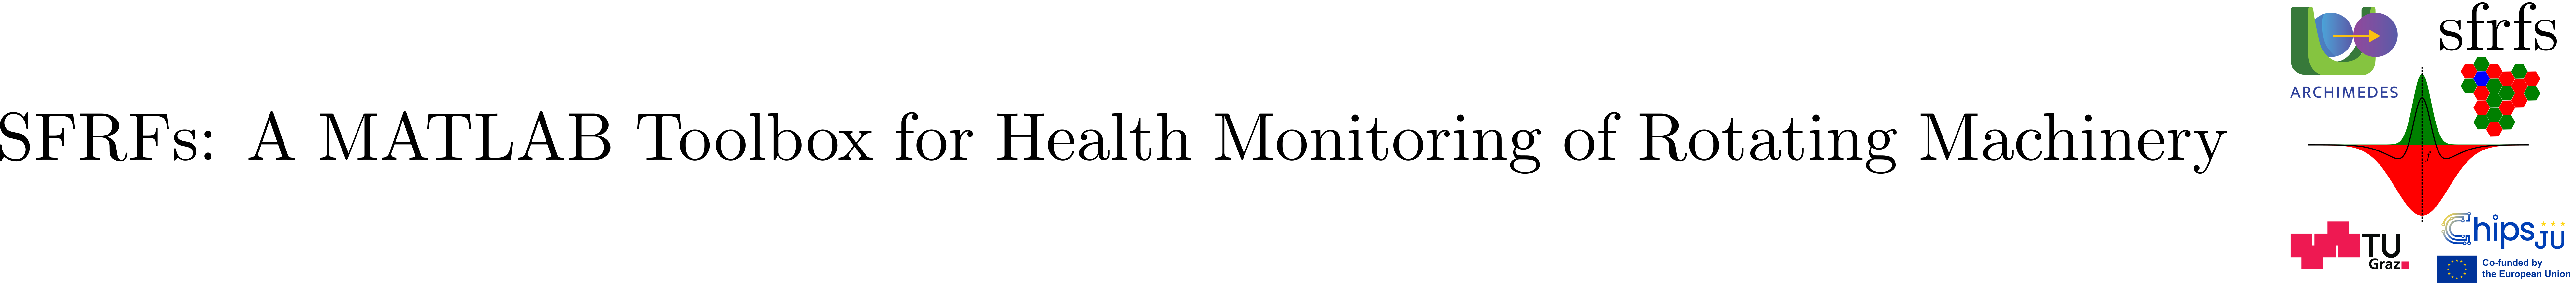

# FrequencyMask

## `Summary`

`FrequencyMask` is a lightweight static utility class for generating frequency-domain masks over a specified band. It currently supports both Gaussian and super-Gaussian profiles, enabling flexible shaping of spectral weighting functions.

**Key features:**

- Generates Gaussian masks based on a specified frequency band and a configurable sigma rule.

- Provides super-Gaussian masks with a tunable shape exponent for sharper or flatter profiles.

- Ensures symmetric masks around the band’s center frequency.

- Supports optional normalization of Gaussian masks.

- Enforces input validation for consistency and physical interpretability.

This class provides a compact and extensible foundation for SFRFs processing (see Reference [1]).

## Description

`FrequencyMask` is a lightweight static utility class for constructing frequency-domain gain functions. It currently supports both Gaussian and super-Gaussian profiles, allowing smooth or sharp spectral weighting depending on the selected parameters.

The mask is defined symmetrically around the center of the specified band. In the Gaussian case, the width is derived from the band limits and a configurable sigma rule, with optional area normalization. In the super-Gaussian case, the shape is controlled by an exponent that smoothly interpolates between Laplacian-like, Gaussian, and near-rectangular profiles.

### Methods

#### gaussian

Generates a Gaussian frequency-domain mask over a specified band.

**Syntax**

- `G = FrequencyMask.gaussian(f, band)`

- `G = FrequencyMask.gaussian(f, band, sigmaRule)`

- `G = FrequencyMask.gaussian(f, band, sigmaRule, normalize)`

**Parameters**

**Output**

#### `superGauss`

Generates a super-Gaussian frequency-domain mask over a specified band.

**Syntax**

- `G = FrequencyMask.superGauss(f, band, beta)`

**Parameters**

#### **Output**

#### See also 

[`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx')), [`SFRFsParameters`](matlab:open('./SFRFsParameters.mlx'))

## `Example`

### `Gaussian profiles`

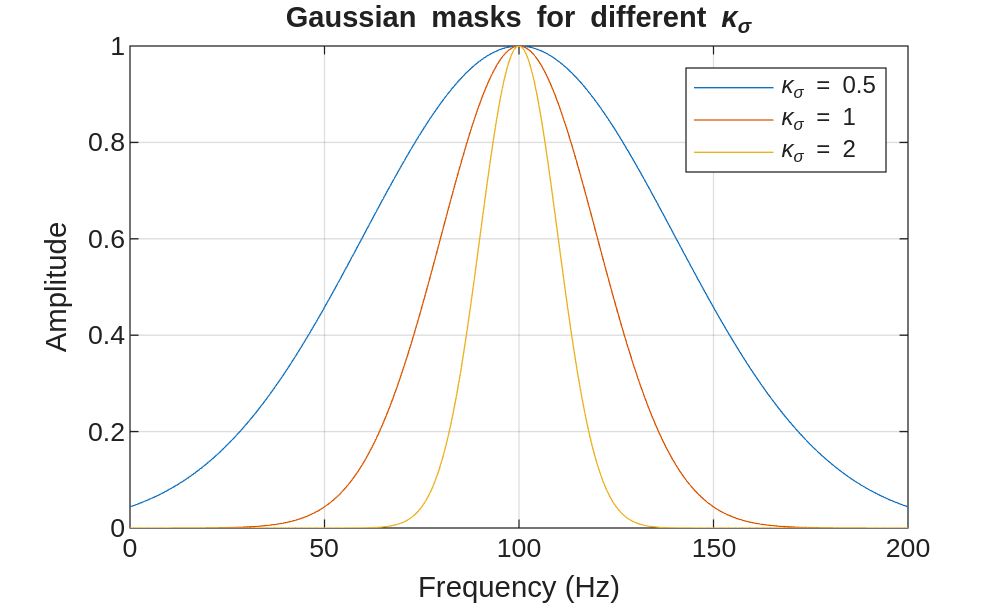


% Frequency vector (Hz)
f = linspace(0, 200, 1000)';

% Monitoring band [fMin fMax]
band = [80 120];

% Generate Gaussian masks with different sigma rules
G_half = FrequencyMask.gaussian(f, band, 0.5);
G_one  = FrequencyMask.gaussian(f, band, 1);
G_two  = FrequencyMask.gaussian(f, band, 2);

% Plot
figure
plot(f, G_half); hold on
plot(f, G_one)
plot(f, G_two)
grid on

xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Gaussian masks for different \kappa_\sigma')

legend( ...
    '\kappa_\sigma = 0.5', ...
    '\kappa_\sigma = 1', ...
    '\kappa_\sigma = 2', ...
    'Location','northeast')

### Super-Gaussian profiles

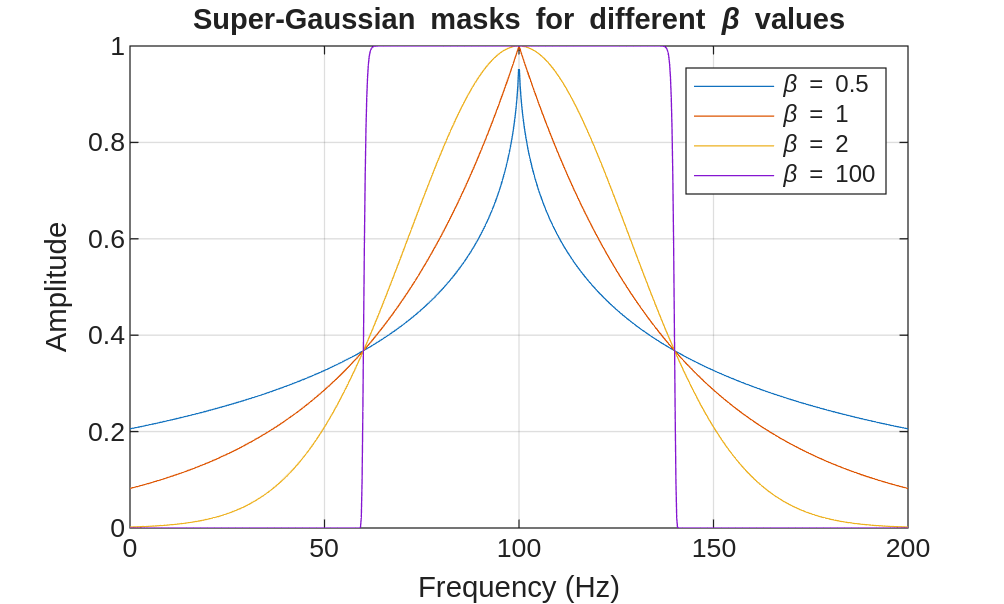

% Frequency vector (Hz)
f = linspace(0, 200, 1000)';

% Monitoring band [fMin fMax]
band = [80 120];

% Generate super-Gaussian masks
G_05  = FrequencyMask.superGauss(f, band, 0.5);
G_1   = FrequencyMask.superGauss(f, band, 1);
G_2   = FrequencyMask.superGauss(f, band, 2);
G_100 = FrequencyMask.superGauss(f, band, 100);

% Plot
figure
plot(f, G_05); hold on
plot(f, G_1)
plot(f, G_2)
plot(f, G_100)
grid on

xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Super-Gaussian masks for different \beta values')

legend( ...
    '\beta = 0.5', ...
    '\beta = 1', ...
    '\beta = 2', ...
    '\beta = 100', ...
    'Location','northeast')

## API documentation

### MATLAB help

help FrequencyMask

  FrequencyMask Utility class for computing frequency domain masks
 
  Current support:
    - Gaussian masks.
    - Super-Gaussian masks.
        (Super-Gaussian includes Gaussian as a special case but 
         is parameterized differently to allow varying shape.)

    Documentation for FrequencyMask
       doc FrequencyMask




### MATLAB documentation

doc FrequencyMask

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

Source code for the class can be found in [FrequencyMask](matlab:open('../../FrequencyMask.m')).

## Test

Unit testing for the class is implemented in [TestFrequencyMask](matlab:open('../../../tests/TestFrequencyMask.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestFrequencyMask');

Running TestFrequencyMask
.......... .
Done TestFrequencyMask
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestFrequencyMask/testGaussianBasicFunctionality                                 | Passed
TestFrequencyMask/testGaussianNormalization                                      | Passed
TestFrequencyMask/testGaussianDefaultArguments                                   | Passed
TestFrequencyMask/testGaussianSigmaRuleEffect                                    | Passed
TestFrequencyMask/testGaussianSingleFrequencyInput                               | Passed
TestFrequencyMask/testInvalidGaussianInputs                                      | Passed
TestFrequencyMask/testSuperGaussBasicFunctionality                               | Passed
TestFrequencyMask/testSuperGaussShapeEffect                                      | Passed
TestFrequencyMask/testSuperGaussScalarInput                                      | Passed
TestFreque

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784)

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).